[y, Fs] = audioread("2nzjqq9p.mp3");
disp(Fs);

       44100



sound(y, 0.5*Fs)


disp(size(y));

      333552           2



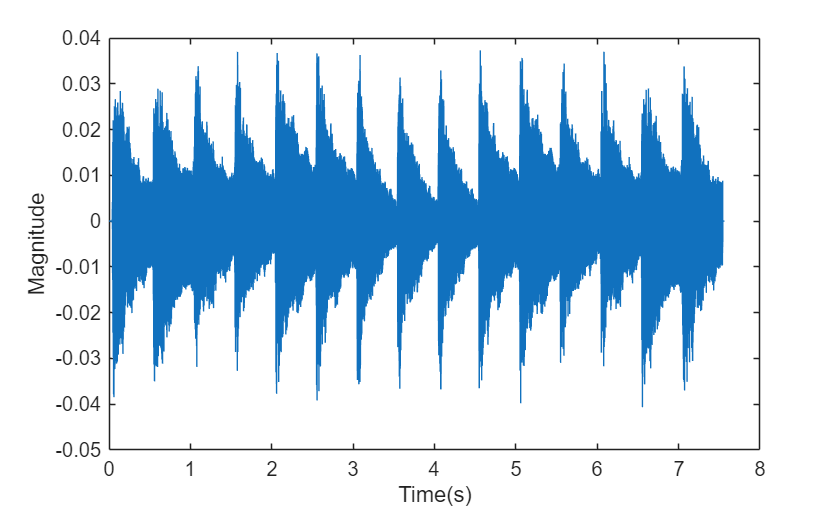

mag = y(:, 1);
t = (1:length(mag))/Fs;
plot(t, mag)
xlabel("Time(s)");
ylabel("Magnitude");

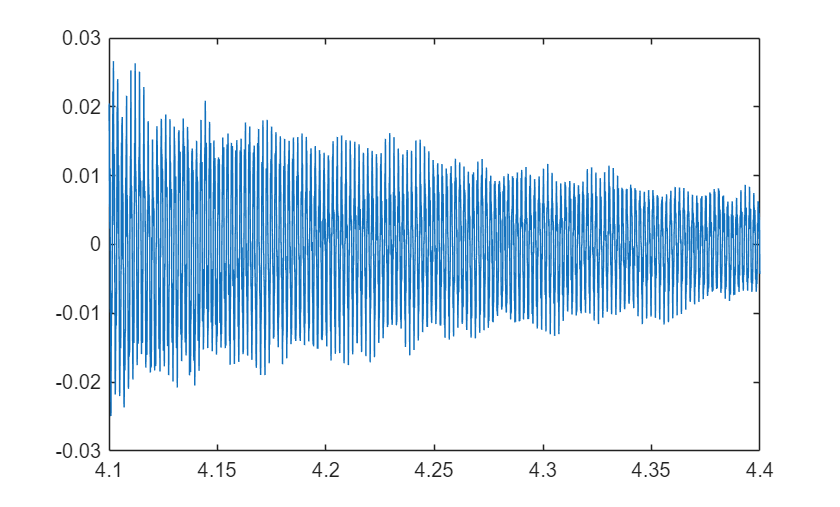

t0 = 4.1;
t1 = 4.4;

mag_clipped = mag(t > t0 & t < t1);
t_clipped = t(t > t0 & t < t1);
plot(t_clipped, mag_clipped);

L = length(mag_clipped);
frequency_spectrum = fft(mag_clipped);
magnitude_spectrum = abs(frequency_spectrum);
shifted_spectrum = fftshift(magnitude_spectrum);
frequency = Fs/L*(-L/2:L/2-1);


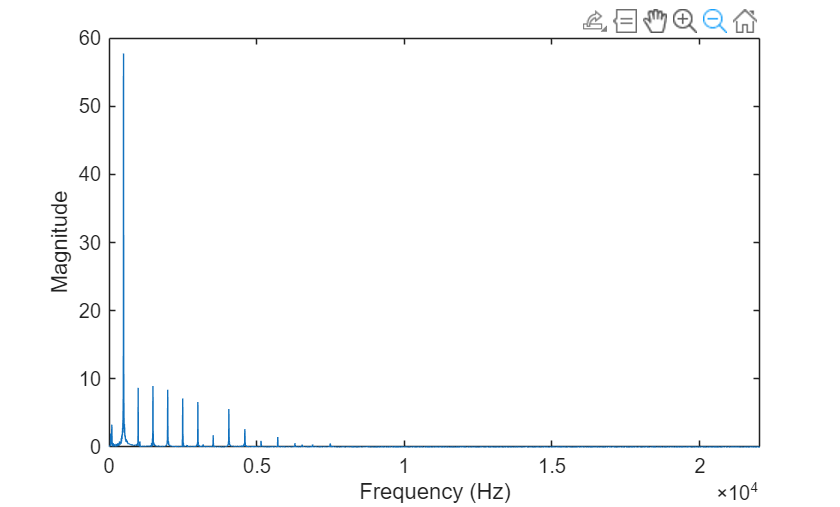

plot(frequency, shifted_spectrum)
xlim([0, Inf])
xlabel('Frequency (Hz)');
ylabel('Magnitude');

[peaks, locs] = findpeaks(shifted_spectrum(frequency>0));
[B, I] = sort(peaks, 'descend');

freqs = frequency(frequency>0);
freq_idxes = locs(I);
peak_freqs = freqs(freq_idxes);
peak_freqs = peak_freqs(1:5)

peak_freqs = 1.0e+03 *

    0.4917    1.4884    0.9884    1.9885    2.4952


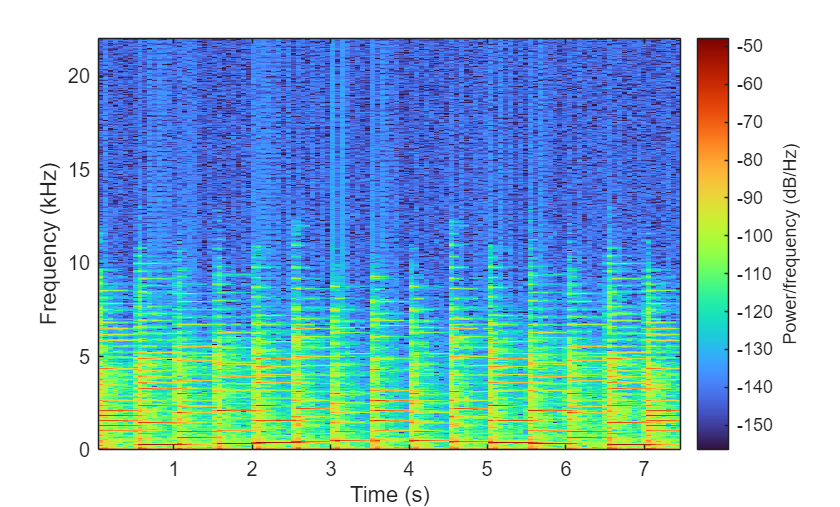

spectrogram(mag, floor(length(mag)/60), [], [], Fs, "yaxis")
colormap turbo;